We consider a clamped-pinned beam. With such a boundary condition, the first two modes have near 1:3 internal resonance as follows


$$\omega_2=3\omega_1(1+\epsilon\sigma_1)$$


with $\epsilon\sigma_1=0.0801$.

Nayfeh [1] inverstigated the forcec response of such a system under external harmonic response. Specifically, modal expansion (with linear modes) is used to transfer PDEs to a set of ODEs


$$\ddot{u}_n+\omega_n^2u_n=\epsilon\left(-2c_n\dot{u}_n+F_n\cos\lambda t+\nu\sum_{m,p,q}\alpha_{nmpq}u_mu_pu_q\right), n=1,\cdots,$$


Then multiple scale perturbation method is used to study the forced response curve. Interestingly, when the excitation frequency is around the second natural frequency, there exits solution branches where the amplitude of the first mode dominiates the system response. Here we use SSM reduction to study such a system.

[1] Nayfeh, A. H., Mook, D. T., & Sridhar, S. (1974). Nonlinear analysis of the forced response of structural elements. *The Journal of the Acoustical Society of America*, *55*(2), 281-291.

## Setup Dynamical System

clear all;
epsilon = 1e-4;
c  = 100;
f = 5/epsilon;
n = 10;               % number of modes
Fext = zeros(n,1);    % excitation at modal coordinate
Fext(1) = f;
[mass,damp,stiff,fnl,fext] = build_model(c,Fext,epsilon,n);

Getting nonlinearity coefficients
Calculating coefficients
L2 norm of phi1 is 1
L2 norm of phi2 is 1
L2 norm of phi3 is 1
L2 norm of phi4 is 1
L2 norm of phi5 is 1
L2 norm of phi6 is 1
L2 norm of phi7 is 1
L2 norm of phi8 is 1
L2 norm of phi9 is 1
L2 norm of phi10 is 1
Saving coefficients



% Create 
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% Forcing
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas);

## Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.593810e-03
modal damping ratio for 2 mode is 8.004681e-04
modal damping ratio for 3 mode is 3.837148e-04
modal damping ratio for 4 mode is 2.243713e-04
modal damping ratio for 5 mode is 1.470421e-04

 The first 10 eigenvalues are given as 
  -0.0100 + 3.8553i
  -0.0100 - 3.8553i
  -0.0100 +12.4927i
  -0.0100 -12.4927i
  -0.0100 +26.0610i
  -0.0100 -26.0610i
  -0.0100 +44.5690i
  -0.0100 -44.5690i
  -0.0100 +68.0077i
  -0.0100 -68.0077i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 1,'notation','multiindex');
resonant_modes = [1 2 3 4];
order = 3;
outdof = [1 2];

## Primary resonance of the first mode

freqrange = [0.98 1.06]*imag(D(1));
set(S.FRCOptions, 'nCycle',500, 'initialSolver', 'forward');
set(S.contOptions, 'PtMX', 300, 'h_max', 0.5);
set(S.FRCOptions,'outdof', outdof, 'omegaSampStyle', 'cocoBD');
start = tic;
FRC_ep1 = S.FRC_cont_ep('isol',resonant_modes, order, [1 3], 'freq', freqrange);

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.05E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.03E-01 MB

 Run='isol.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.25e-01  2.38e+01    0.0    0.0    0.0
   1   1  5.09e-01  1.26e+00  1.04e-01  2.38e+01    0.0    0.0    0.0
   2   1  1.00e+00  3.85e-01  1.81e-02  2.38e+01    0.0    0.0    0.0
   3   1  1.00e+00  8.11e-03  3.47e-04  2.38e+01    0.0    0.0    0.0
   4   1  1.00e+00  7.84e-06  1.28e-07  2.38e+01    0.0    0.0    0.0
   5   1  1.00e+00  3.01e-09  1.80e-14  2.38e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   2.3797e+01      1  

timings.FRC_ep1 = toc(start)

timings = struct with fields:
    FRC_ep1: 9.9969


#### Load Nayfeh's solution for comparison

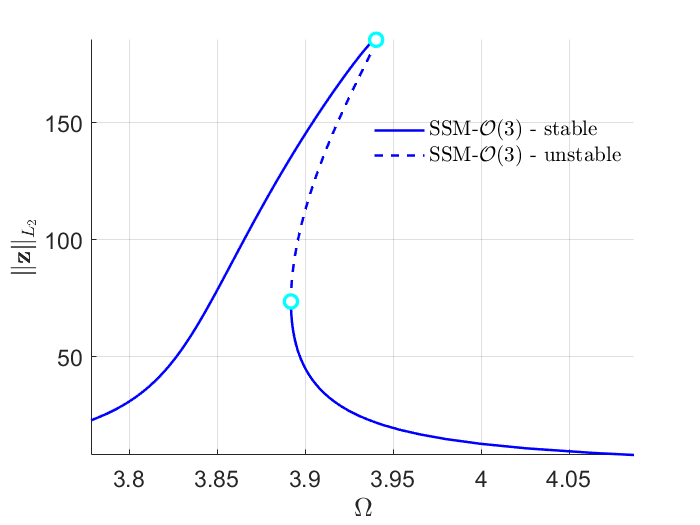

f1 = figure('Name','P1-Norm');
f2 = figure('Name',['P1-Amplitude at DOFs ' num2str(outdof)]);
figs = [f1, f2];
plot_FRC_full(FRC_ep1,outdof,order,'freq','lines',figs,'blue')

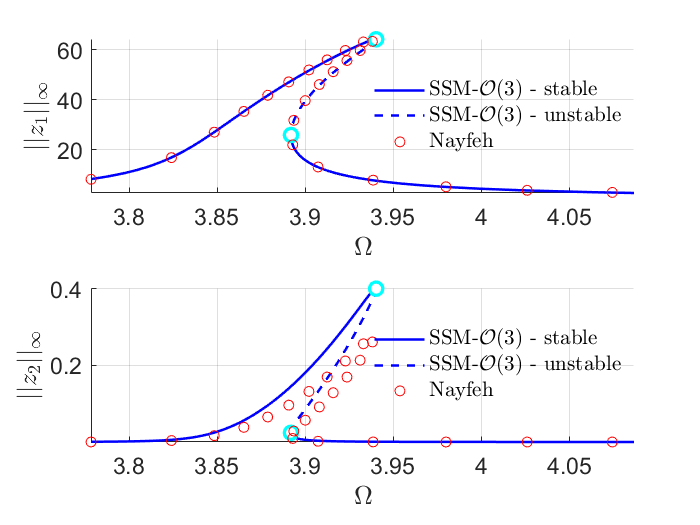



Nayfeh1 = load('NayfehFirstMode');
om1 = 3.8553;
omsamp = om1*(1+Nayfeh1.epsilon*Nayfeh1.SIG2);
figure(f2); hold on
subplot(2,1,1)
plot(omsamp(1:100:end),Nayfeh1.A1(1:100:end),'ro','DisplayName','Nayfeh');
subplot(2,1,2)
plot(omsamp(1:100:end),Nayfeh1.A2(1:100:end),'ro','DisplayName','Nayfeh');

#### Verification using COCO


 Run='bd1.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.19e-01  2.33e+02    0.0    0.0    0.0
   1   1  1.00e+00  5.77e-02  1.08e-05  2.33e+02    0.0    0.2    0.0
   2   1  1.00e+00  2.21e-04  4.32e-12  2.33e+02    0.0    0.4    0.1
   3   1  1.00e+00  5.03e-10  8.09e-14  2.33e+02    0.0    0.5    0.1

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:03   2.3281e+02      1  EP      3.7796e+00   1.6624e+00   1.0000e+00   8.4151e+00   6.5931e-04
    6  00:00:24   2.7340e+02      2  EP      3.7782e+00   1.6630e+00   1.0000e+00   8.2760e+00   6.2617e-04

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp1         amp2
    0  00:00:25   2.3281e+02      3  EP      3.7796e+00   1.6624e+00   1.0000e+00   

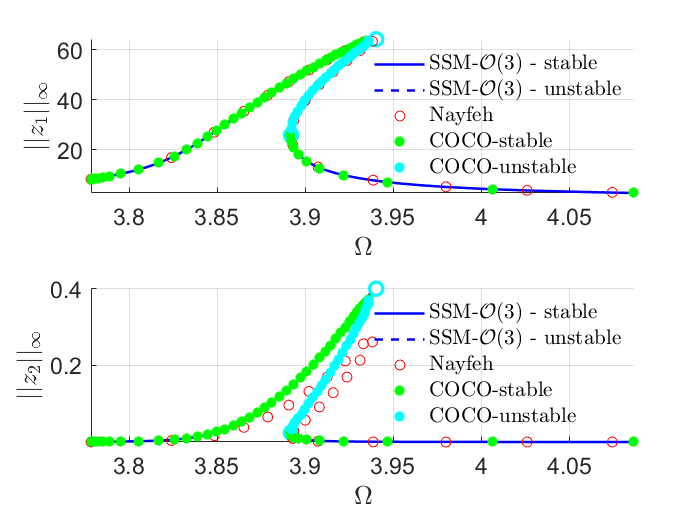

nCycles = 500;
coco = cocoWrapper(DS, nCycles, outdof);
set(coco.Options, 'PtMX', 1000, 'NTST',20, 'dir_name', 'bd1');
set(coco.Options, 'NAdapt', 1, 'h_max', 200, 'MaxRes', 1);
coco.initialGuess = 'linear';
start = tic;
bd1 = coco.extract_FRC(freqrange);

timings.cocoFRCbd1 = toc(start)

timings = struct with fields:
       FRC_ep1: 9.9969
    cocoFRCbd1: 764.1391


### Nonzero forcing at other modes $f_1=f_2=\cdots=f_{10}\neq0$

Fext = zeros(n,1)+f;  % excitation at modal coordinate
[~,~,~,~,fext2] = build_model(c,Fext,epsilon,n);

Getting nonlinearity coefficients
Loaded coefficients from storage


coeffs = [fext2 fext2]/2;
DS.add_forcing(coeffs, kappas);
outdof2 = [2 3]

outdof2 =      2     3



set(S.FRCOptions,'outdof',outdof2)
start = tic;
FRC_ep2 = S.FRC_cont_ep('isolAllf',resonant_modes, order, [1 3], 'freq', freqrange);

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.05E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.03E-01 MB

 Run='isolAllf.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          6.25e-01  2.38e+01    0.0    0.0    0.0
   1   1  5.09e-01  1.26e+00  1.04e-01  2.38e+01    0.0    0.0    0.0
   2   1  1.00e+00  3.85e-01  1.81e-02  2.38e+01    0.0    0.0    0.0
   3   1  1.00e+00  8.11e-03  3.47e-04  2.38e+01    0.0    0.0    0.0
   4   1  1.00e+00  7.84e-06  1.28e-07  2.38e+01    0.0    0.0    0.0
   5   1  1.00e+00  3.01e-09  1.80e-14  2.38e+01    0.0    0.0    0.0

 STEP      TIME        ||U||  LABEL  TYPE            om         rho1         rho2          th1          th2          eps
    0  00:00:00   2.3797e+01     

timings.FRC_ep2 = toc(start)

timings = struct with fields:
       FRC_ep1: 9.9969
    cocoFRCbd1: 764.1391
       FRC_ep2: 10.3059


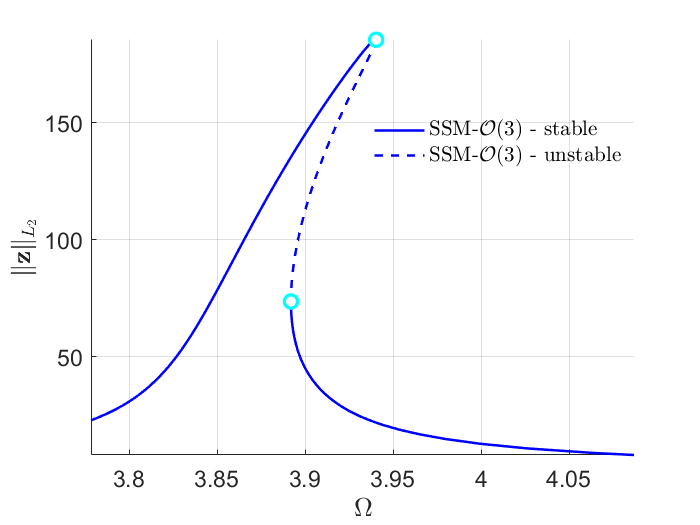

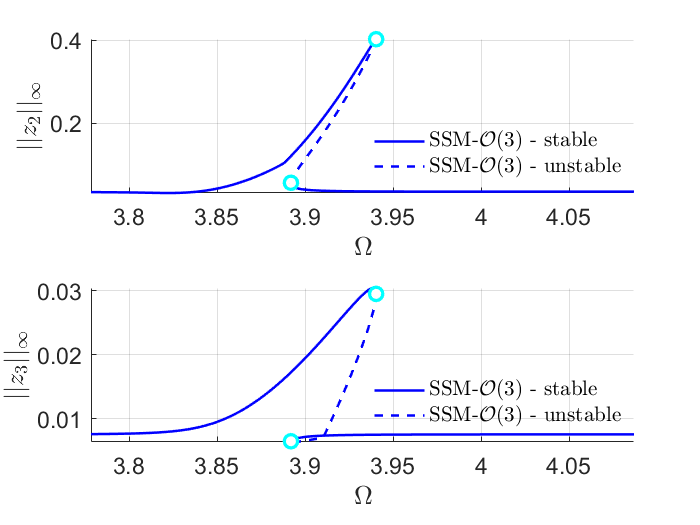

f1 = figure('Name','P1allF-Norm');
f2 = figure('Name',['P1allF-Amplitude at DOFs ' num2str(outdof2)]);
figs = [f1, f2];
plot_FRC_full(FRC_ep2,outdof2,order,'freq','lines',figs,'blue')

**Verification using COCO**


 Run='bd2.FRC': Continue primary family of periodic orbits.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT     GAMMA     ||d||     ||f||     ||U||   F(x)  DF(x)  SOLVE
   0                          1.19e-01  2.33e+02    0.0    0.0    0.0
   1   1  1.00e+00  5.85e-02  1.11e-05  2.33e+02    0.0    0.2    0.0
   2   1  1.00e+00  2.16e-04  4.56e-12  2.33e+02    0.0    0.3    0.0
   3   1  1.00e+00  4.77e-10  7.75e-14  2.33e+02    0.0    0.5    0.1

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp2         amp3
    0  00:00:03   2.3281e+02      1  EP      3.7796e+00   1.6624e+00   1.0000e+00   3.4609e-02   7.5810e-03
    6  00:00:30   2.7338e+02      2  EP      3.7782e+00   1.6630e+00   1.0000e+00   3.4638e-02   7.5780e-03

 STEP      TIME        ||U||  LABEL  TYPE         omega    po.period          eps         amp2         amp3
    0  00:00:31   2.3281e+02      3  EP      3.7796e+00   1.6624e+00   1.0000e+00   

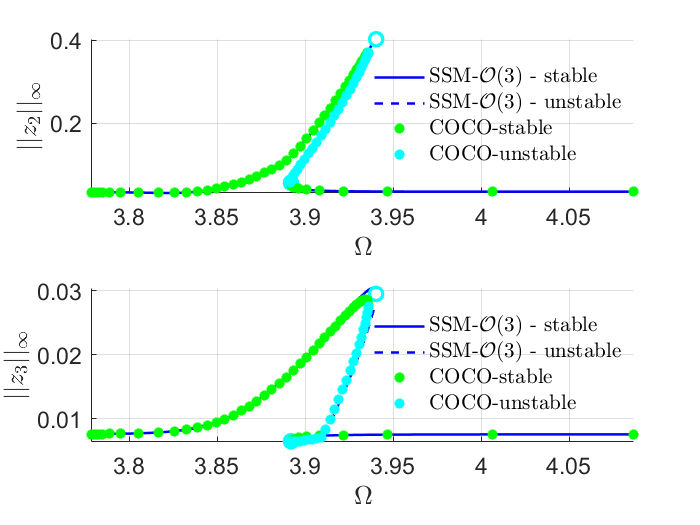

coco = cocoWrapper(DS, nCycles, outdof2);
set(coco.Options, 'PtMX', 1000, 'NTST',20, 'dir_name', 'bd2');
set(coco.Options, 'NAdapt', 1, 'h_max', 200, 'MaxRes', 1);
coco.initialGuess = 'linear';
start = tic;
bd2 = coco.extract_FRC(freqrange);

timings.cocoFRCbd2 = toc(start)

timings = struct with fields:
       FRC_ep1: 9.9969
    cocoFRCbd1: 764.1391
       FRC_ep2: 10.3059
    cocoFRCbd2: 870.2890


## Primary resonance of the second mode

***epsilon = 1e-4; c = 10; f2 = 40/epsilon; ***

c  = 10;
f = 40/epsilon;
n = 10;               % number of modes
Fext = zeros(n,1);    % excitation at modal coordinate
Fext(2) = f;
[mass,damp,stiff,fnl,fext] = build_model(c,Fext,epsilon,n);

Getting nonlinearity coefficients
Loaded coefficients from storage



% Create dynamical system
DS = DynamicalSystem();
set(DS,'M',mass,'C',damp,'K',stiff,'fnl',fnl);
set(DS.Options,'Emax',5,'Nmax',10,'notation','multiindex')
% Forcing
kappas = [-1; 1];
coeffs = [fext fext]/2;
DS.add_forcing(coeffs, kappas);

## Linear Modal analysis

[V,D,W] = DS.linear_spectral_analysis();

Due to high-dimensionality, we compute only the first 5 eigenvalues with the smallest magnitude. These would also be used to compute the spectral quotients
Assuming a proportional damping hypthesis with symmetric matrices
modal damping ratio for 1 mode is 2.593810e-04
modal damping ratio for 2 mode is 8.004681e-05
modal damping ratio for 3 mode is 3.837148e-05
modal damping ratio for 4 mode is 2.243713e-05
modal damping ratio for 5 mode is 1.470421e-05

 The first 10 eigenvalues are given as 
  -0.0010 + 3.8553i
  -0.0010 - 3.8553i
  -0.0010 +12.4927i
  -0.0010 -12.4927i
  -0.0010 +26.0610i
  -0.0010 -26.0610i
  -0.0010 +44.5690i
  -0.0010 -44.5690i
  -0.0010 +68.0077i
  -0.0010 -68.0077i



**Choose Master subspace (perform resonance analysis)**

S = SSM(DS);
set(S.Options, 'reltol', 1.0,'notation','multiindex');
resonant_modes = [1 2 3 4];
order = 3;
outdof = [1 2];
freqrange = [0.94 1.12]*imag(D(3));

set(S.FRCOptions, 'omegaSampStyle', 'cocoBD');
set(S.contOptions, 'h_max', 5, 'PtMX', 250);
set(S.FRCOptions, 'initialSolver', 'fsolve');
set(S.FRCOptions, 'coordinates', 'cartesian'); 

**Non-zero **$a_1$** (reproduce Nayfehs' solutions to get initial guess)**

p0 = [imag(D(3));1];
z0 = [97.8562  -55.4066    1.9095    0.9820]'*1e3;
set(S.FRCOptions,'p0',p0,'z0',z0);
set(S.FRCOptions,'outdof',outdof);
start = tic;
FRC_ep21 = S.FRC_cont_ep('isol2',resonant_modes, order, [1/3 1], 'freq', freqrange);

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.05E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.03E-01 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol2.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT    

timings.FRC_ep21 = toc(start)

timings = struct with fields:
       FRC_ep1: 9.9969
    cocoFRCbd1: 764.1391
       FRC_ep2: 10.3059
    cocoFRCbd2: 870.2890
      FRC_ep21: 14.6822


#### Load Nayfeh's solution for comparison

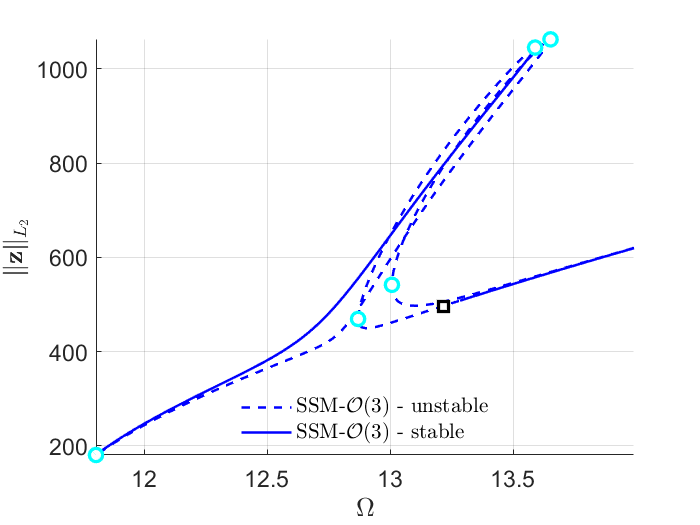

f1 = figure('Name','P2nonzero-Norm');
f2 = figure('Name',['P2nonzero-Amplitude at DOFs ' num2str(outdof)]);
figs = [f1, f2];
plot_FRC_full(FRC_ep21,outdof,order,'freq','lines',figs,'blue')

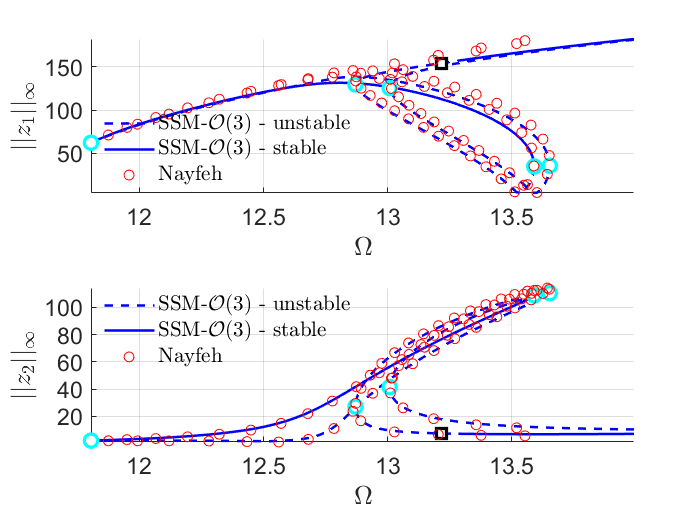



Nayfeh21 = load('NayfehSecondModeA1Nequal0.mat');
om2 = 12.4927;
omsamp = om2*(1+1e-4*Nayfeh21.SIG2);
figure(gcf); hold on
subplot(2,1,1)
plot(omsamp(1:150:end),Nayfeh21.A1(1:150:end),'ro','DisplayName','Nayfeh');
subplot(2,1,2)
plot(omsamp(1:150:end),Nayfeh21.A2(1:150:end),'ro','DisplayName','Nayfeh');

**Zero **$a_1$** upper branch**

set(S.FRCOptions,'p0',[],'z0',[]);
start = tic;
FRC_ep22 = S.FRC_cont_ep('isol3',resonant_modes, order, [1/3 1], 'freq', freqrange);

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.05E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.03E-01 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol3.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT    

timings.FRC_ep22 = toc(start)

timings = struct with fields:
       FRC_ep1: 9.9969
    cocoFRCbd1: 764.1391
       FRC_ep2: 10.3059
    cocoFRCbd2: 870.2890
      FRC_ep21: 14.6822
      FRC_ep22: 2.4051


**Zero **$a_1$** lower branch**

p0 = [1.06*imag(D(3));1];
z0 = [0 0 1 1]';
set(S.FRCOptions,'p0',p0,'z0',z0);
start = tic;
FRC_ep23 = S.FRC_cont_ep('isol4',resonant_modes, order, [1/3 1], 'freq',freqrange);

sigma_out = 1
sigma_in = 1
Manifold computation time at order 2 = 00:00:00
Estimated memory usage at order  2 = 7.05E-02 MB
Manifold computation time at order 3 = 00:00:00
Estimated memory usage at order  3 = 1.03E-01 MB

Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>

 Run='isol4.ep': Continue equilibria along primary branch.

    STEP   DAMPING               NORMS              COMPUTATION TIMES
  IT SIT    

timings.FRC_ep23 = toc(start)

timings = struct with fields:
       FRC_ep1: 9.9969
    cocoFRCbd1: 764.1391
       FRC_ep2: 10.3059
    cocoFRCbd2: 870.2890
      FRC_ep21: 14.6822
      FRC_ep22: 2.4051
      FRC_ep23: 2.7423


#### Plot zero $a_1$ results in the same figure

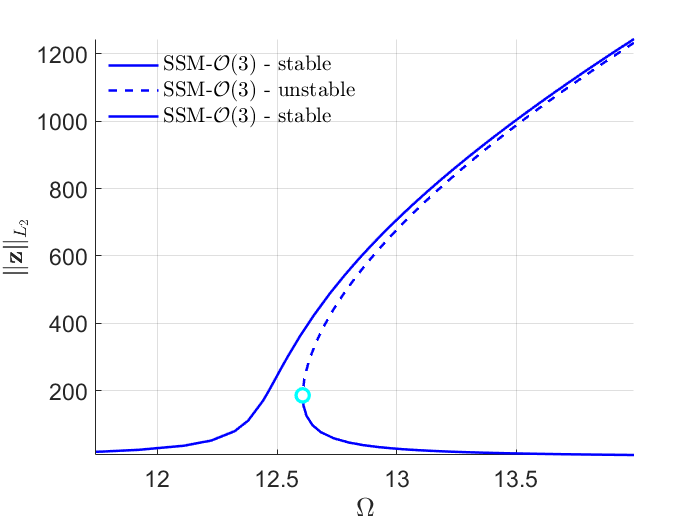

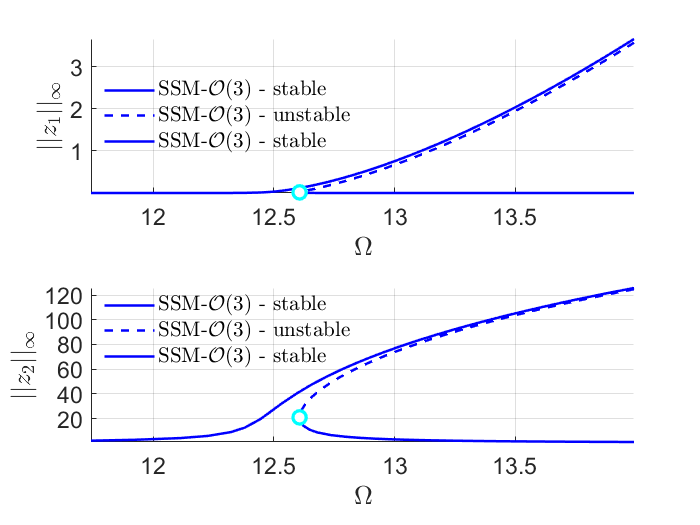

f1 = figure('Name','P2zero-Norm');
f2 = figure('Name',['P2zero-Amplitude at DOFs ' num2str(outdof)]);
figs = [f1, f2];
plot_FRC_full(FRC_ep22,outdof,order,'freq','lines',figs,'blue')
plot_FRC_full(FRC_ep23,outdof,order,'freq','lines',figs,'blue')

#### Load Nayfeh's solution for comparison

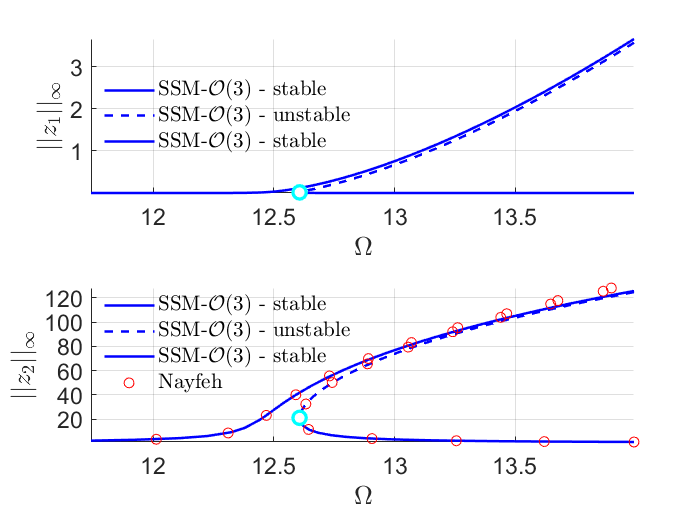

Nayfeh21 = load('NayfehSecondModeA1equal0.mat');
om2 = 12.4927;
omsamp = om2*(1+Nayfeh21.epsilon*Nayfeh21.Sig2);
figure(gcf); hold on
subplot(2,1,2)
plot(omsamp(1:100:end),Nayfeh21.A2(1:100:end),'ro','DisplayName','Nayfeh');